eeg2_tr=trial7.eeg1;
emg2_tr=trial7.eeg7;
eeg2_tr=eeg2_tr*(3.3/4096);
emg2_tr=emg2_tr*(3.3/4096);
f_data2=length(emg2_tr)/120;
t_data2=1/f_data2;
Time_d2=[0:1:length(eeg2_tr)-1]*t_data2;

plot(Time_d2,eeg2_tr)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

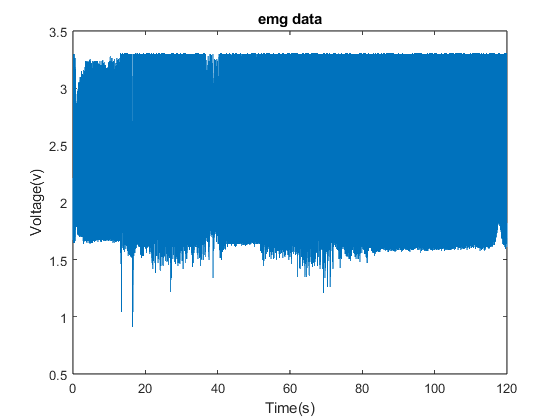

plot(Time_d2,emg2_tr)
title('emg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

eeg2_tr_fft=fft(eeg2_tr);
eeg2_tr_fft(1)=0;
eeg2_tr=ifft(eeg2_tr_fft);

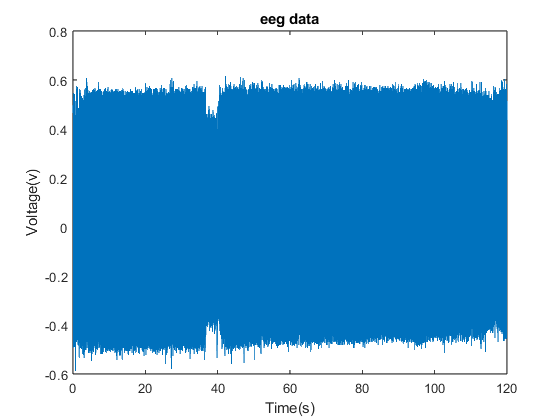

plot(Time_d2,eeg2_tr)
title('eeg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

emg2_tr_fft=fft(emg2_tr);
emg2_tr_fft(1)=0;
emg2_tr=ifft(emg2_tr_fft);

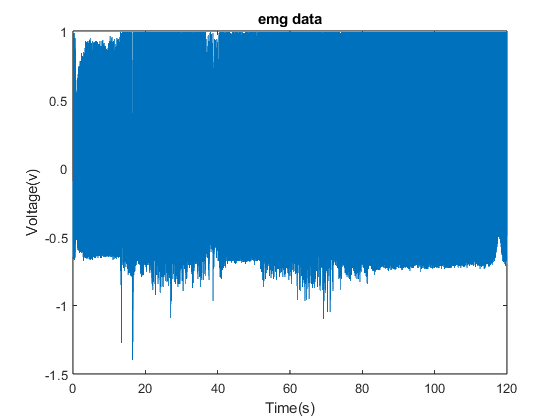

plot(Time_d2,emg2_tr)
title('emg data')
xlabel('Time(s)')
ylabel('Voltage(v)')

pspectrum(emg2_tr,f_data2,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-60,"OverlapPercent",90,"TimeResolution",1.8);

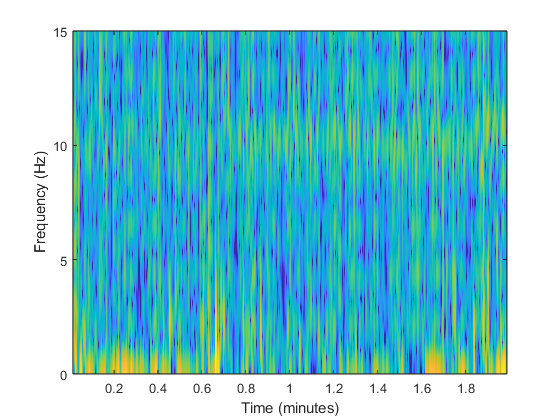

Dot indexing is not supported for variables of this type.

Error in datacursormode>localGetObj (line 199)
hTool = hMode.ModeStateData.DataCursorTool;

Error in datacursormode (line 159)
hTool = localGetObj(hMode,action);

Error in 

pspectrum(eeg2_tr,f_data2,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-60,"OverlapPercent",90,"TimeResolution",1.8);

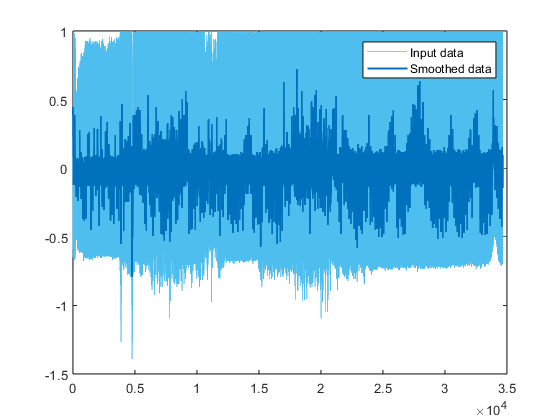

% Smooth input data
emg_smooth2 = smoothdata(emg2_tr,"movmean",[3 2]);

% Display results
clf
plot(emg2_tr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(emg_smooth2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

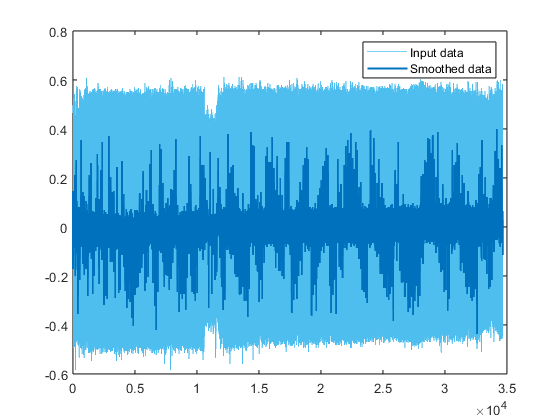

% Smooth input data
eeg_smooth2 = smoothdata(eeg2_tr,"movmean",[4 1]);

% Display results
clf
plot(eeg2_tr,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eeg_smooth2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Smoothed data")
hold off
legend

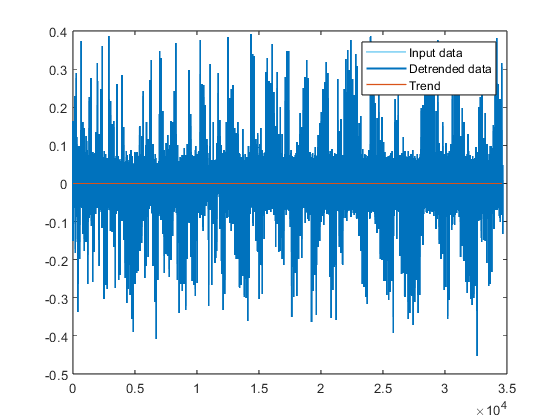

% Remove trend from data
eeg_smooth2 = detrend(eeg_smooth2);

% Display results
clf
plot(eeg_smooth2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(eeg_smooth2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(eeg_smooth2-eeg_smooth2,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

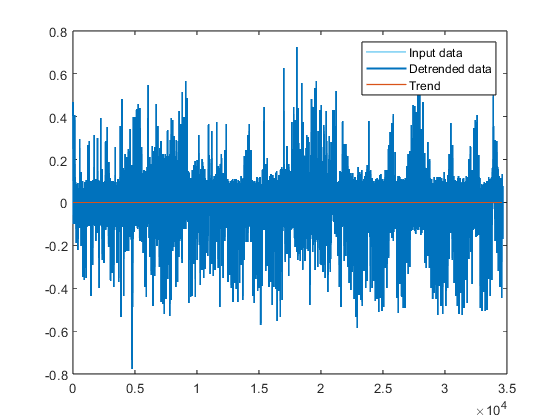

% Remove trend from data
emg_smooth2 = detrend(emg_smooth2);

% Display results
clf
plot(emg_smooth2,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(emg_smooth2,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(emg_smooth2-emg_smooth2,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

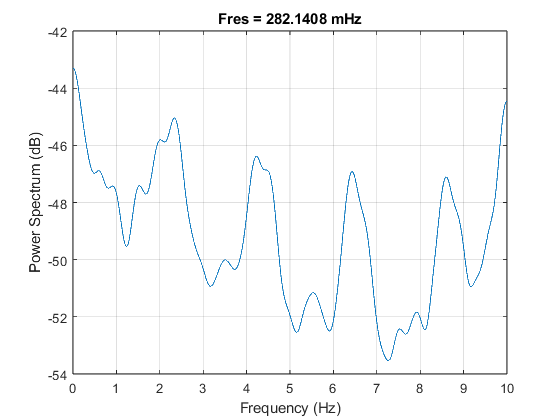

pspectrum(eeg_smooth2,f_data2,"power","FrequencyLimits",[0,10])%"FrequencyLimits",[0,15],"MinThreshold",-40,"OverlapPercent",90,"TimeResolution",1);

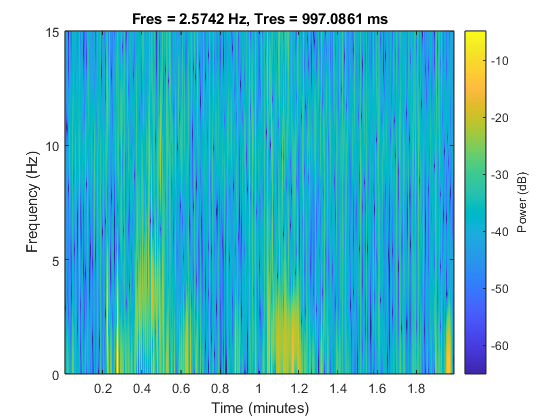

pspectrum(emg_smooth2,f_data2,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-65,"OverlapPercent",99,"TimeResolution",1);

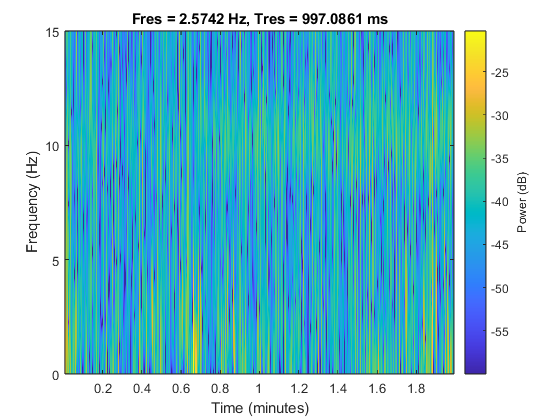

pspectrum(eeg_smooth2,f_data2,"spectrogram","FrequencyLimits",[0,15],"MinThreshold",-60,"OverlapPercent",99,"TimeResolution",1);

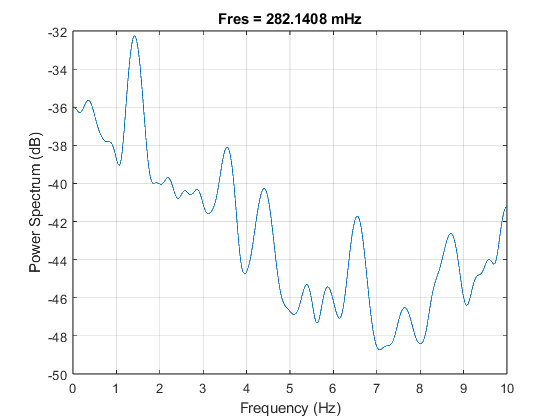

pspectrum(emg_smooth2,f_data2,"power","FrequencyLimits",[0,10])

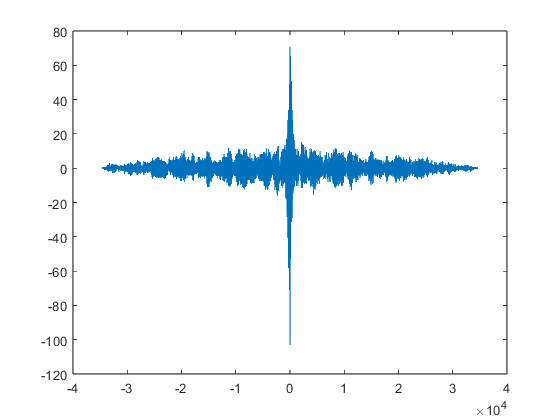

[correlated_eeg_emg2,lags2]=xcorr(eeg_smooth2,emg_smooth2);

plot(lags2,correlated_eeg_emg2);

output_eeg_emg_7=[eeg2_tr,emg2_tr];
output_eeg_emg_7_smooth=[eeg_smooth2,emg_smooth2];


writematrix(output_eeg_emg_7_smooth,'D:\matlab\ymaps_code\data\output_eeg_emg_7_smooth.csv');
writematrix(output_eeg_emg_7,'D:\matlab\ymaps_code\data\output_eeg_emg_7.csv');

videoFile = 'D:\matlab\ymaps_code\data\trial7_eeg ';
writerObj = VideoWriter(videoFile,'MPEG-4');
writerObj.FrameRate = 1; 

open(writerObj);
figure;
windowsize=306

windowsize = 306

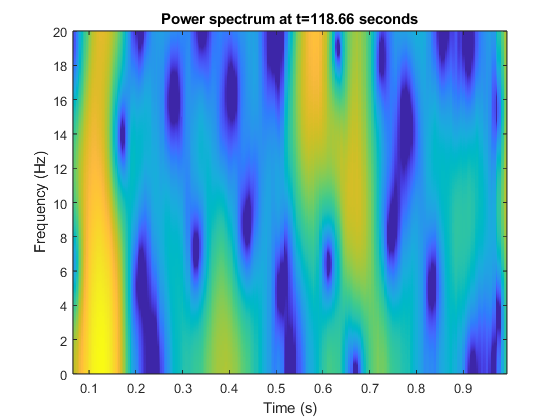

for i=1:windowsize:length(eeg_smooth2)-windowsize
    eeg_smooth2_seg=eeg_smooth2(i:i+windowsize-1);
%     [p_seg,f_Seg,t_seg]=pspectrum(eeg_smooth2_seg,f_data2,"power");
%     plot(f_Seg,10*log(p_seg));
%     xlim([0,40]);
%     

   [p_seg,f_Seg,t_seg]=pspectrum(eeg_smooth2_seg,f_data2,"spectrogram","FrequencyLimits",[0,20],"OverlapPercent",99,"MinThreshold",-50,"Leakage",0.9);
   
%     aterfall(t_seg,f_Seg,p_seg)
    imagesc(t_seg, f_Seg, 10 * log10(abs(p_seg))); % Display in dB
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
   
    title(sprintf('Power spectrum at t=%.2f seconds',i/f_data2));
    frame = getframe(gcf);
    writeVideo(writerObj, frame);
    pause(1/1200);
    
    
end

videoFile = 'D:\matlab\ymaps_code\data\trial7_emg';
writerObj = VideoWriter(videoFile,"MPEG-4");
writerObj.FrameRate = 1; 

open(writerObj);
figure;
windowsize=306

windowsize = 306

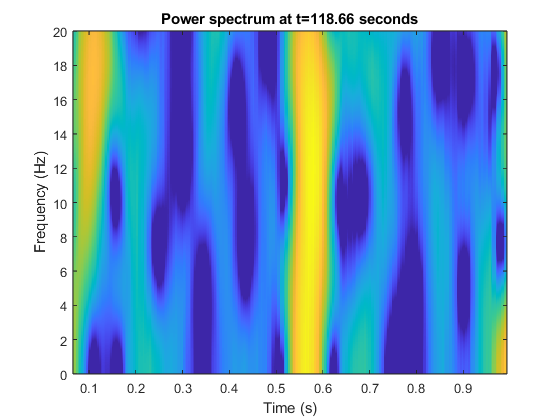

for i=1:windowsize:length(emg_smooth2)-windowsize
    emg_smooth2_seg=emg_smooth2(i:i+windowsize-1);
%     [p_seg,f_Seg,t_seg]=pspectrum(eeg_smooth2_seg,f_data2,"power");
%     plot(f_Seg,10*log(p_seg));
%     xlim([0,40]);
%     

   [p_seg,f_Seg,t_seg]=pspectrum(emg_smooth2_seg,f_data2,"spectrogram","FrequencyLimits",[0,20],"OverlapPercent",99,"MinThreshold",-40,"Leakage",0.9);
   
%     aterfall(t_seg,f_Seg,p_seg)
    imagesc(t_seg, f_Seg, 10 * log10(abs(p_seg))); % Display in dB
    axis xy;
    xlabel('Time (s)');
    ylabel('Frequency (Hz)');
   
    title(sprintf('Power spectrum at t=%.2f seconds',i/f_data2));
    frame = getframe(gcf);
    writeVideo(writerObj, frame);
    pause(1/1200);
    
    
end